# Tutorial: Scaling to the  UC3M-HPC Cluster

## System Requirements

In order to submit MATLAB jobs to the cluster, you will need to have MATLAB and Parallel Computing Toolbox installed on your machine.  See the following table for system requirements.

## Architecture

The workflow we're going to follow is "remote submission".  That is, we will be submitting jobs from our desktop, which are then submitted to a scheduler (SLURM) and then run on the cluster.

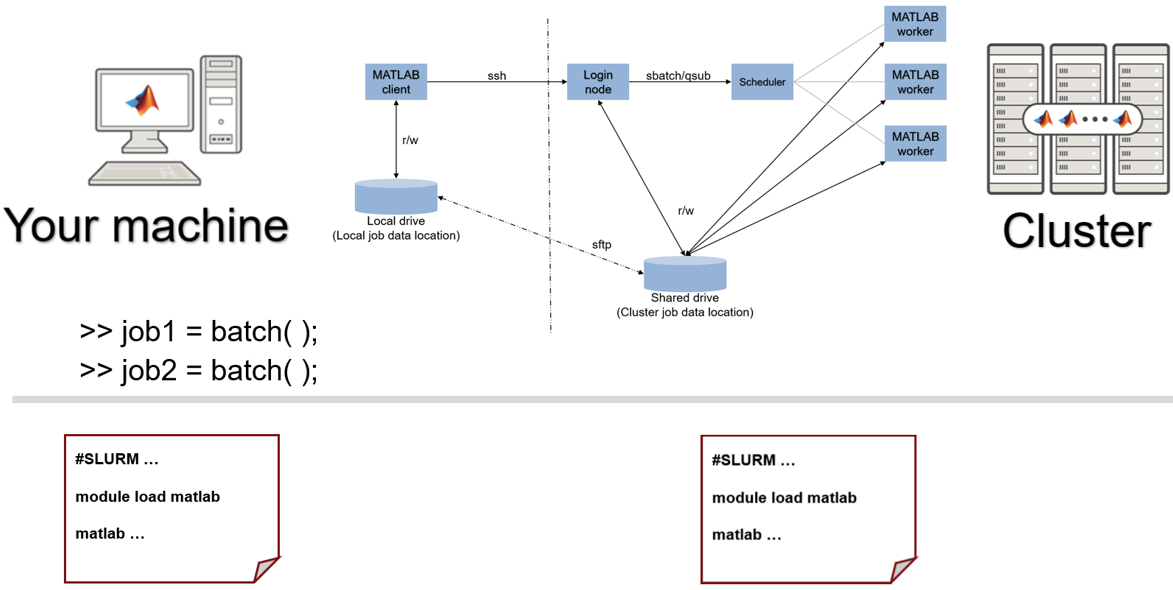

## Getting Started

All information for getting started with submitting jobs to the cluster can be found at the [**Getting Started with Parallel Computing with MATLAB page**](https://c3-uc3m.github.io/c3-web/user_docs/matlab/).  The site includes links to a ZIP-file with all the necessary files as well as examples for configuring and submitting jobs to the cluster.

In order to submit jobs to the cluster, we first need to create a new parallel environment ("profile").  The profile provides hooks into MATLAB for submitting a job, getting the state of the job, and for deleting the job.  Creating the profile only needs to be done once for each version of MATLAB you'll be submitting jobs from.

### Download plugin scripts

Click on the [**Getting Started with Parallel Computing with MATLAB page**](https://c3-uc3m.github.io/c3-web/user_docs/matlab/) and scroll the section for downloading the plugin scripts.

The contents of the ZIP must be unzipped into the folder returned by the MATLAB function `userpath`.  Verify the contents of the ZIP file have been properly extracted by ensuring the `configCluster` exists in the folder returned by `userpath`.

### Create the profile

Next, we'll generate the new profile.  Run `configCluster`.  You will be first prompted to select a cluster to configure.  For this tutorial, we will be using the Insomnia cluster.  Next, you will be prompted for your cluster username.

configCluster

Go to the Home toolstrip, click Parallel > Select Parallel Environment to verify that the new profile has been created.

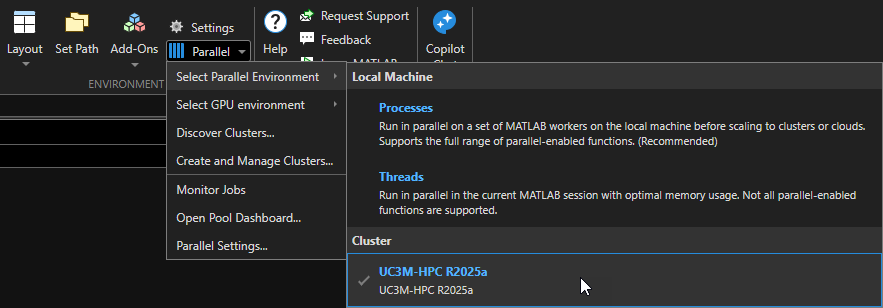

### Configure the profile

A scheduler may have a set of required submission parameters (e.g., walltime).  Run `parcluster` and assign it to the variable `c`.

% Get a handle to the cluster object
c = parcluster();

Doing so will display any required submission parameters (if they do not have values assigned to them).  One optional, but useful, parameter is EmailAddress.  Setting this will notify us when a job starts, ends, or is aborted.

% Set to your own email address
% c.AdditionalProperties.EmailAddress = "a-user@uc3m.es";

% Store the profile for future use
c.saveProfile

Look at other settable properties.

c.AdditionalProperties

To disable properties, such as email notification, set the property to the empty string, false, or 0 (depending on the type).

% c.AdditionalProperties.EmailAddress = "";

We'll see how to get partition names later.

## Job Submission

MATLAB has several job submission functions, two of which are [parpool](https://www.mathworks.com/help/parallel-computing/parpool.html) and [`batch`](https://www.mathworks.com/help/parallel-computing/batch.html).  In this demo, we'll focus on using `batch`.

### Authentication

If using a private key to authenticate, ensure the key is OpenSSH compliant.  PuTTY (for Windows) uses a different format and will need to be converted to an OpenSSH format (look at PuTTYgen).

### Single core

Let's submit our first job to the cluster.  We'll use the `batch` command to submit a job, querying for the location the MATLAB worker starts in.

% Get a handle to the cluster object
c = parcluster();

% Set a WallTime for the job
c.AdditionalProperties.WallTime = "00:03:00";

% Submit job
job1 = c.batch(@pwd,1,{}, CurrentFolder='.', AutoAddClientPath=false);

`batch` then submits the job asynchronously, allowing us to run other code in our MATLAB client, while the job continues to run on the cluster.

% Run a command while the job is running
randperm(6)

% Go back and query the state of the job.  Once the job has finished
% running, we'll fetch the results.
job1.State

% Block MATLAB while the job continues to run
job1.wait

% The job has finished running, fetch the results
folder = job1.fetchOutputs{1}

### Multi-core, multi-node

The first example didn't require any additional workers to run.  In this example, our code runs a parfor-loop, requiring a pool of workers.

% Get a handle to the cluster object
c = parcluster();

% Set the processors per node.  Setting procs per node to zero doesn't
% require any specific constraints on the specific number of processors per
% node.
c.AdditionalProperties.ProcsPerNode = 10;
c.AdditionalProperties.WallTime = "00:15:00";

% Submit asynchronous job
job2 = c.batch(@parallel_fcn,1,{100}, CurrentFolder='.', AutoAddClientPath=false, Pool=19);

Let's wait for the job to finish, then fetch the results

job2.wait
result = job2.fetchOutputs{:}

Notice only *time* came back, not the matrix `A`.  Why?

We'll see another way to retrieve `A` later.

% Cleanup
c.AdditionalProperties.ProcsPerNode = 0;
c.saveProfile

### Simulink

This demo models the thermal heating of a house, sweeping temperatures between a range of degrees.

To parallelize a parameter sweep of a Simulink model, we'll use the [SimulationInput](https://www.mathworks.com/help/simulink/slref/simulink.simulationinput.html) object to temporarily store block parameters (in our case, the temperatures).  We'll supply the Simulation Input object to [`batchsim`](https://www.mathworks.com/help/simulink/slref/batchsim.html).

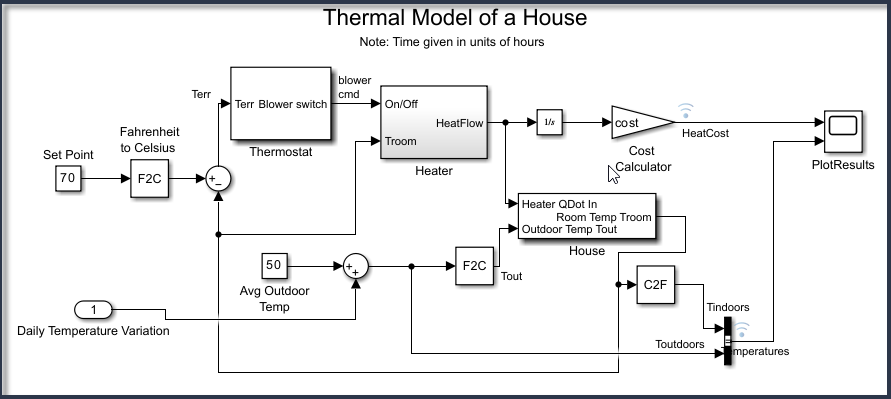

% This demo changes the folder, keep track to reset it later
od = pwd;

% Get a handle to the cluster object
c = parcluster();

% Set additional job properties
c.AdditionalProperties.WallTime = "00:15:00";

% Model heating system of a house
mdl = 'ex_sldemo_househeat';

% Open and load model
openExample("simulink/ViewTheContentsOfTheSimulinkSimulationInputObjectExample",supportingFile=mdl)

% Define temperatures
temps = 62:4:84;
tlen = length(temps);

% Initialize Simulation Inputs.  Set the temperature from 62 to 84.
in(1:tlen) = Simulink.SimulationInput(mdl);
for tidx = 1:tlen
    in(tidx) = in(tidx).setBlockParameter([mdl '/Set Point'], 'Value',num2str(temps(tidx)));
end

% Submit Simulink job
simJob = batchsim(c,in, Pool=tlen);

simJob.wait
simJob.diary

% Reset to original folder and close our Simulink model
cd(od)
bdclose all

## Scaling Further

### Multi-threading

By default, each worker (which is a process) is assigned one computational thread.  Let's see the difference and impact adding threads has on our job.

% Get a handle to the cluster object
c = parcluster();

% Set additional job properties
c.AdditionalProperties.WallTime = "00:05:00";

% Increase the threads from 1 to 32
c.NumThreads = 16;

% Solve a system of linear equations with matrix size 10000 x 10000
% 1 thread: 11.34s
% 16 threads: 2.15s
job3 = c.batch(@solve_sle,1,{10000}, CurrentFolder='.', AutoAddClientPath=false);

% Tag the job to find it easier in Job Monitor
job3.Tag = "CPU + " + c.NumThreads + " thread(s)";

% Wait for the job to finish before fetching the results
job3.wait

% Fetch the CPU timing
tc = job3.fetchOutputs{1}

% Cleanup
c.NumThreads = 1;
c.saveProfile

### Hybrid parallelization

By combining multi-threading and multiprocessing, we get the best of both worlds.

% Get a handle to the cluster object
c = parcluster();

% Set additional job properties
c.AdditionalProperties.WallTime = "00:05:00";

% Increase the threads from 1 to 32
c.NumThreads = 8;

% Solve an array of system of linear equations with matrix size 10000 x 10000
% 1 thread: 22.3s
% 8 threads: 3.49s
job4 = c.batch(@solve_array_sle,1,{10000,6}, CurrentFolder='.', AutoAddClientPath=false, Pool=3);

% Tag the job to find it easier in Job Monitor
job4.Tag = "CPU + " + c.NumThreads + " thread(s) + " + job4.NumWorkersRange(1) + " worker(s)";

% Wait for the job to finish before fetching the results
job4.wait

% Fetch the CPU timing
tc = job4.fetchOutputs{1}

% Cleanup
c.NumThreads = 1;
c.saveProfile

### GPUs

Some jobs will benefit from running on a GPU rather than a CPU.  To run a GPU job, we'll need to request additional resources.

% Get a handle to the cluster object
c = parcluster();

% Request GPU
c.AdditionalProperties.GPUsPerNode = 1;

% Set additional job properties
c.AdditionalProperties.MemPerCPU = "8GB";
c.AdditionalProperties.WallTime = "00:15:00";

% Increase the threads from 1 to 32
c.NumThreads = 8;

% Solve a system of linear equations with matrix size 15000 x 15000.  Compare
% solving on a CPU and GPU.
job5 = c.batch(@solve_sle_cpu_and_gpu,2,{15000}, CurrentFolder='.', AutoAddClientPath=false);

% Query why the job isn't running
willRun(job5)

% Wait for the job to finish before fetching the results
job5.wait

% tc: CPU timing (34.75s w/ 1t, 10.22s w/ 8t)
% gc: GPU timing (4.62s)
[tc, gc] = job5.fetchOutputs{:}

% Cleanup
c.AdditionalProperties.GPUsPerNode = 0;
c.AdditionalProperties.MemPerCPU = "4GB";
c.NumThreads = 1;
c.saveProfile

#### GPU Memory

There are important considerations when working with GPUs.  One of the most common roadblocks is trying to utilize more memory on a card than is available.  Let's submit the same job again, just with a much larger array size.  What happens when you try to fetch results?

% Get a handle to the cluster object
c = parcluster();

% See what types of GPUs are available on the cluster
gCards = clusterGpuCards(c)

% Request GPU
c.AdditionalProperties.GPUsPerNode = 1;

% Set additional job properties
c.AdditionalProperties.WallTime = "00:05:00";

% Solve a system of linear equations with matrix size 25000 x 25000 on the
% GPU only.
job6 = c.batch(@solve_sle_gpu_mem,1,{55000}, CurrentFolder='.', AutoAddClientPath=false);

% Query why the job isn't running
willRun(job6)

% Wait for the job to finish before fetching the results
job6.wait

% Try fetching the results
[gc] = job6.fetchOutputs{:}

% Cleanup
c.AdditionalProperties.GPUsPerNode = 0;
c.AdditionalProperties.MemPerCPU = "4GB";
c.saveProfile

#### GPU Data Transfer

A second important factor when working with a GPU is data transfer overhead between the CPU and the GPU.  Most of today's HPC systems do not have shared memory between these two pieces of hardware.  Instead, data transfer is typically done over PCIe and as a result, you incur a performance penalty.

% Get a handle to the cluster object
c = parcluster();

% Request GPU
c.AdditionalProperties.GPUsPerNode = 1;

% Set additional job properties
c.AdditionalProperties.WallTime = "00:15:00";

% Solve a system of linear equations with matrix size 15000 x 15000.  Compare
% the total time of the function and the computation time only.
job7 = c.batch(@solve_sle_gpu,2,{15000}, CurrentFolder='.', AutoAddClientPath=false);

% Query why the job isn't running
willRun(job7)

% Wait for the job to finish before fetching the results
job7.wait

% Try fetching the results
[t_comp, t_total] = job7.fetchOutputs{:}

% Cleanup
c.AdditionalProperties.GPUsPerNode = 0;
c.saveProfile

### Retrieving data files

Pulling data back from the cluster can be an unnecessary expense.  To avoid this, only pull data or files back as needed.

efile = "error-file.mat";
if exist(efile,"file")
    delete(efile)
end

% Get a handle to the cluster object
c = parcluster();

% Set additional job properties
c.AdditionalProperties.WallTime = "00:05:00";

% Submit asynchronous job
job8 = c.batch(@parallel_fcn,1,{100}, CurrentFolder='.', AutoAddClientPath=false, Pool=3);

% Define FileStore and update action
store = job8.FileStore;
store.KeyUpdatedFcn = @download_data_file;

% Let's wait for the job to finish, then fetch the results
job8.wait, pause(10)
if exist(efile,"file")
    whos('-file',efile)
end

## Development Tools

### Job Monitor

We've seen how to fetch the outputs of jobs running functions, but what if we've restarted MATLAB (and lost our variable workspace).  We can view the arrays of jobs from our cluster object.  

% Get a handle to the cluster object
c = parcluster();

% Fetch a specific job ID, 1
j = c.findJob(ID=1);
j.fetchOutputs{:}

Alternatively, we can use the Job Monitor to view jobs info, e.g., diary, error messages, and outputs.

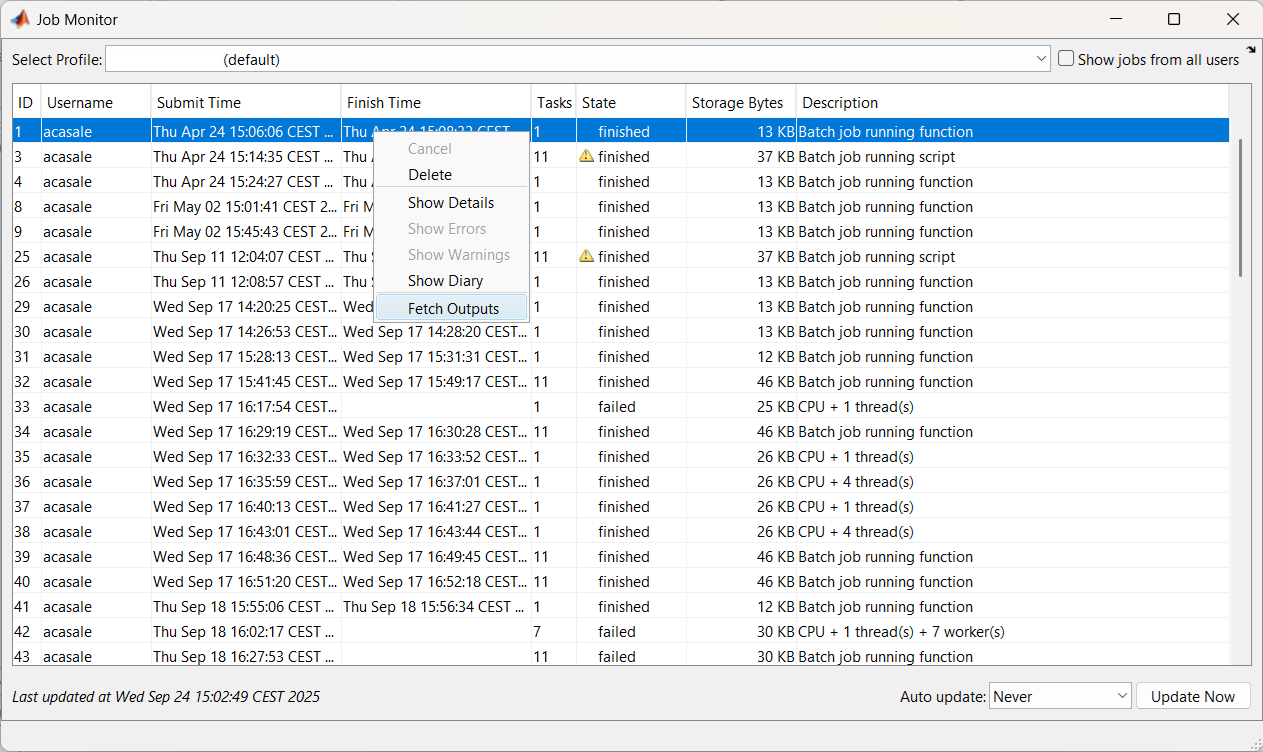

### Troubleshooting

When debugging jobs, there are tools to use, such as scheduler ID and log files.

% Get a handle to the cluster object
c = parcluster();

% Set additional job properties
c.AdditionalProperties.WallTime = "00:15:00";

% Submit asynchronous job
job9 = c.batch(@parallel_fcn,1,{100}, CurrentFolder='.', AutoAddClientPath=false, Pool=3);

% Wait for the job to finish
job9.wait

% Display the captured diary
job9.diary

% The scheduler ID is assigned by the scheduler and used to track the
% status and errors of the job
job9.getTaskSchedulerIDs{:}

% Display the scheduler log files
%c.getDebugLog(job7.Tasks)
c.getDebugLog(job9)


## Getting Further Help

Scan the code to request free MathWorks support for submitting jobs to your HPC cluster.

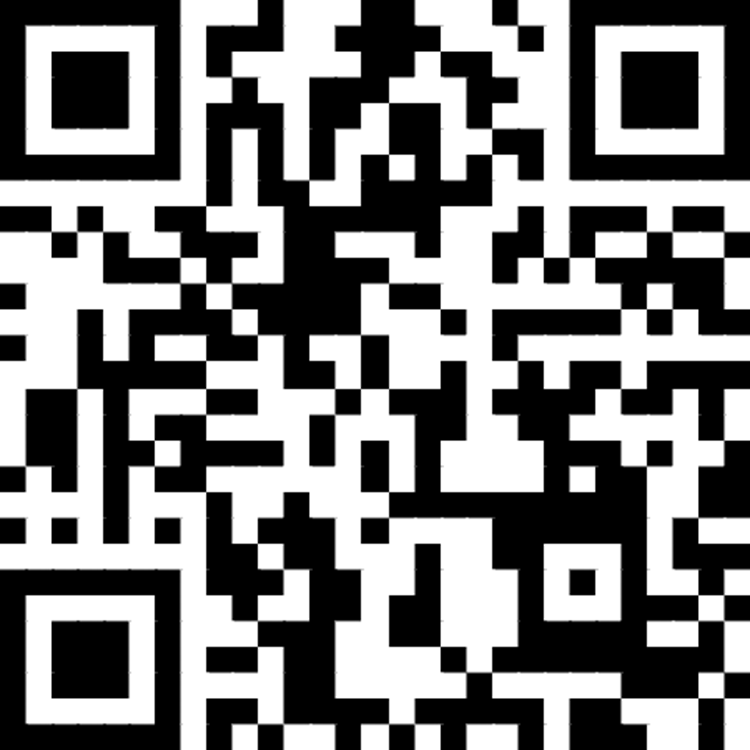

## Local Helper Functions

function [sim_t, A] = parallel_fcn(iter,thold)

if nargin==1, thold = 0.05; end

disp("Start sim")

A = nan(iter,1);
t0 = tic;
parfor idx = 1:iter
    A(idx) = rand;
    pause(0.1)
    fprintf("Running iteration: " + idx + "\n")
end
sim_t = toc(t0);

disp("Finished")

if max(A(:))>thold
    % We have a failure.  Store the results into the filestore and send
    % back to the MATLAB client.
    disp("Found error.  Logging data.")

    save RESULTS A

    store = getCurrentFileStore;
    key = "error-file";
    store.copyFileToStore("RESULTS.mat", key)
end

end

function download_data_file(store, key)

switch key
    case "error-file"
        disp("Found error.  Logging file.")
        % Filename (to write to serialize data to)
        destination = strcat(key,".mat");

        % Create local file
        store.copyFileFromStore(key,destination)
    otherwise
        disp("Unknown key:" + key)
end

end

function [t_c, t_g] = solve_sle_cpu_and_gpu(len)

% Workaround only for R2024a and R2024b using MIGs
%init_gpus

tc = tic;
A = rand(len);
b = rand(len,1);
x = A\b;
t_c = toc(tc);

tg = tic;
gA = gpuArray.rand(len);
gB = gpuArray.rand(len,1);
gx = gA\gB;
t_g = toc(tg);

disp("Speed up ratio: " + num2str(t_c/t_g))

end

function [t_comp, t_total] = solve_sle_gpu(len)

% Workaround only for R2024a and R2024b using MIGs
%init_gpus

% Create variables on CPU, then move them over to GPU
t_total = tic;
A = rand(len);
gA = gpuArray(A);
B = rand(len,1);
gB = gpuArray(B);

% Perform calculation on the GPU
t_comp = tic;
gX = gA\gB;
t_comp = toc(t_comp);


% Gather results back to CPU and wait for transfer to finish
x = gather(gX);
wait(gpuDevice);
t_total = toc(t_total);

% Display results
disp(['Computation only time: ' num2str(t_comp)])
disp(['Total time: ' num2str(t_total)])

end

function t_c = solve_sle(len)

tc = tic;
A = rand(len);
b = rand(len,1);
x = A\b;
t_c = toc(tc);

end

function [t_g] = solve_sle_gpu_mem(len)

% Workaround only for R2024a and R2024b using MIGs
%init_gpus

tg = tic;
gA = gpuArray.rand(len);
gB = gpuArray.rand(len,1);
gx = gA\gB;
t_g = toc(tg);

disp("Computation time: " + num2str(t_g))

end

function t_c = solve_array_sle(len,iter)

parfor sidx = 1:iter
    t_c(sidx) = solve_sle(len);
end

end

%#ok<*NASGU,*DEFNU,*ASGLU,*TRYNC>